Considere a cadeia de Markov com o diagrama de transição de estados seguinte:

a) Defina em Matlab a matriz de transição de estados T, com T(ij) sendo a probabilidade de ir do estado j para o estado i num úncio passo.

M = [ 0.8,   0,   0, 0.3,   0
      0.2, 0.6,   0, 0.2,   0
        0, 0.3,   1,   0,   0
        0, 0.1,   0, 0.4,   0  
        0,   0,   0, 0.1,   1]

M =     0.8000         0         0    0.3000         0
    0.2000    0.6000         0    0.2000         0
         0    0.3000    1.0000         0         0
         0    0.1000         0    0.4000         0
         0         0         0    0.1000    1.0000



sum(M);

b) Faça em gráfico com a probabilidade de, começando no estado 1, estar no estado 2 ao fim de n passos, com n a variar de 1 até 100. Justifique o que observa.

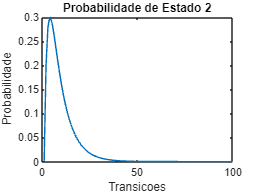

x = [1 0 0 0 0]';

z = zeros(1,100);
z(1) = 0;

for i = 2:100
    x = M * x;
    z(i) = x(2);
end

plot(1:100, z)
title('Probabilidade de Estado 2')
xlabel('Transicoes')
ylabel('Probabilidade')

c) Faça um gráfico com a probabilidade de, começando no estado 1, estar no estado 3 ao fim de n passos. Na mesma figura, faça um segundo gráfico com a probabilidade de, comaçndo no estado 1, estar no estado 5 ao fim de n passos. Em ambos os casos, considere n a variar de 1 até 100. Justifique o que observa.

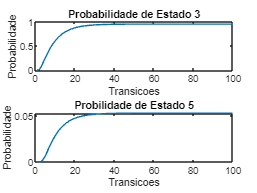

x1 = [1 0 0 0 0]';

z1 = zeros(1, 100);
z1(1) = 0;

for i = 2:100
    x1 = M * x1;
    z1(i) = x1(3);
end

subplot(2, 1, 1);
plot(1:100, z1)
title('Probabilidade de Estado 3')
xlabel('Transicoes')
ylabel('Probabilidade')


x2 = [1 0 0 0 0]';

z2 = zeros(1, 100);
z2(1) = 0;

for i = 2:100
    x2 = M * x2;
    z2(i) = x2(5);
end

subplot(2, 1, 2);
plot(1:100, z2)
title('Probilidade de Estado 5')
xlabel('Transicoes')
ylabel('Probabilidade')

d) Determine a matriz Q

% Matriz de estados canonica

%       1   2   4 3 5
C = [ 0.8   0 0.3 0 0
      0.2 0.6 0.2 0 0 
        0 0.1 0.4 1 0
        0 0.3   0 0 0
        0   0 0.1 0 1]

C =     0.8000         0    0.3000         0         0
    0.2000    0.6000    0.2000         0         0
         0    0.1000    0.4000    1.0000         0
         0    0.3000         0         0         0
         0         0    0.1000         0    1.0000



sum(C);
Q = C(1:3, 1:3)

Q =     0.8000         0    0.3000
    0.2000    0.6000    0.2000
         0    0.1000    0.4000


e) Determine a matriz fundamental F

F = (eye(3) - Q)^-1

F =     5.7895    0.7895    3.1579
    3.1579    3.1579    2.6316
    0.5263    0.5263    2.1053


sum(F);

f) Qual a média (valor esperado) do número de passos antes da absorção começando no estado 1? E começando no estado 2? E se começando no estado 4?

valE = sum(F);
fprintf('A probabilidade de absorção se partir do estado 1 é: %.4f\nDo estado 2 é: %.4f\nDo estado 3 é: %.4f\n', valE);

A probabilidade de absorção se partir do estado 1 é: 9.4737
Do estado 2 é: 4.4737
Do estado 3 é: 7.8947


g) Começando no estado 1, qual é a probabilidade de absorção do estado 3? E do estado 5? Verifique a coerência destes valores com o que observou na alínea 6 (c)

R = C(4:5, 1:3);
B = R*F

B =     0.9474    0.9474    0.7895
    0.0526    0.0526    0.2105



fprintf('P(estado 3) = %.4f, P(estado 5) = %.4f',B(1,1),B(2,1));

P(estado 3) = 0.9474, P(estado 5) = 0.0526